# Chapter 3

## Quality Modelling

Load library paths

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


**Modelling water quality in a tank**

Considering chlorine as a disinfectant, the decay of chlorine in the bulk water (e.g, a water tank), when there are no other inputs, can be modelled using a first-order reaction


$$\frac{dC(t)}{dt} = -k_bC(t)$$


where $k_b$ is a decay constant. The analytical solution of this decay is given below, following the Figure 1 example in Clark 1998. In practice, water taken from a source would be analyzed avery few hours, and a decay-rate coefficient can be computed to match the behaviour.  In general, more complicated models can be considered.

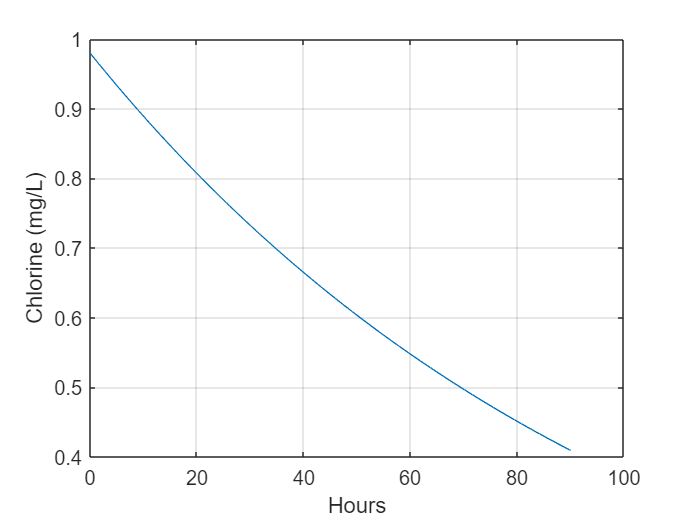

tspan = 0:0.001:90; %in hours
c0 = 0.98;
kb = 0.0097; % first-order decay rate for UWR-OPS
[t,c] = ode23(@(t,c) -kb*c, tspan, c0);
figure
plot(t,c,'-')
xlabel('Hours')
ylabel('Chlorine (mg/L)')
grid on

**Solving the equations in discrete-time**

These equations can also be solved in discrete time, using a numerical approximation (Forward Euler) to formulate a state-space equation. 


$$t = k\Delta t, k\in N$$



$$\frac{C(k+1)-C(k)}{\Delta t} = k_b C(k)$$



$$C(k+1) = (1- \Delta t k_b)
 C(k)$$


This is compared with the analytical solution computed above.

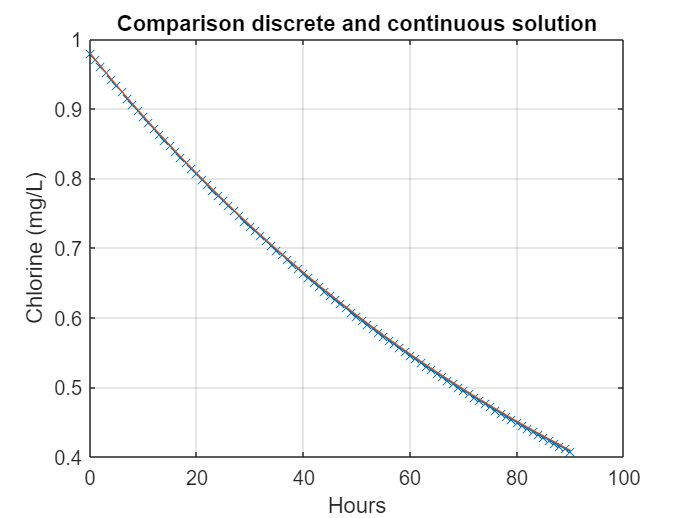

clear C
Dt = 1;
kspan = 0:Dt:90; %in hours
C(1) = 0.98;
kb = 0.0097; % first-order decay rate for UWR-OPS
for k = 1:size(kspan,2)
    C(k+1) = (1- Dt*kb)*C(k);
end

figure
plot(kspan,C(1:end-1),'-x')
xlabel('Hours')
ylabel('Chlorine (mg/L)')
grid on
hold all
plot(t,c,'-')
title('Comparison discrete and continuous solution')

**Modelling tank concenrtation with inputs and outputs & contamination **

In practice, the concentration in a tank depends on the water inflow and its concentration as well as the outflow


$$x_1(k+1)  = x_1(k) + \Delta t(u_1(k) - u_2(k))$$



$$x_2(k+1) = \frac{1}{x_1(k) + \Delta t (u_1(k) - u_2(k))} ((x_1(k) - \Delta tu_2(k))x_2(k) + u_1(k) u_3(k) + x_1(k) k_b \Delta t x(t))$$


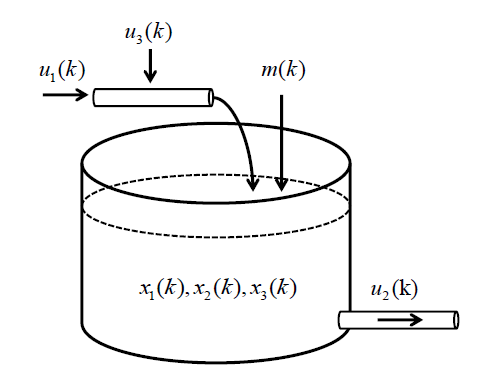

NominalDynamics = @(x,u,dt) [...
    (x(1)+u(1)-u(2));...
    ((x(1)-u(2))*x(2)+u(1)*u(3)+x(1)*dt*kb*x(2))/(x(1)+u(1)-u(2))];
    

**Modelling multi-species reactions**

Disinfectants, can react with other subtances; this can be modelled as a multi-species reactions, which describe the reaction kinetics.


$$\frac{dC}{dt}= f_R(C(t), C_A(t))$$



$$0 = f_a(C(t), C_A(t))$$


**Modelling chlorine reactions as multi-species reactions**

In various studies, Chlorine was found to behave following more complex dynamics, when compared to the linear model. For example, the augmented two-reactant model (Fisher et al. 2016, Fisher et al. 2021) was proposed, using a bilinear formulation. This model assumes a "slow" and a "fast" reactant, with different reaction rates.

(Also check [https://awwa.onlinelibrary.wiley.com/doi/full/10.1002/awwa.1183](https://awwa.onlinelibrary.wiley.com/doi/full/10.1002/awwa.1183)  @ Table 1)

Decay of bulk chlorine concentration (mg/L)


$$\frac{dC_{Cl}}{dt} = - k_f C_f C_{Cl} - k_s C_s C_{Cl}
$$


Decay of "slow" reactants


$$\frac{dC_{s}}{dt} = - k_s C_s C_{Cl}$$


Decay of fast reactants


$$\frac{dC_f}{dt} = - k_f C_f C_{Cl}$$


The reaction coefficients can be provided through the following equation, which depends on the Temperature.


$$k_T = k_{20} \times  \exp[-E/R \times  (20-T)/(273 + 20)/(273 + T)]$$


Disinfection by-products are the output of the reaction of certain disinfectants with reacting substances, such as Trihalomethanes. 


$$\frac{dT}{dt} = k_\alpha (k_f C_f C_{Cl} + k_s C_s C_{Cl})$$


where $k_a$ is the TTHM yield.

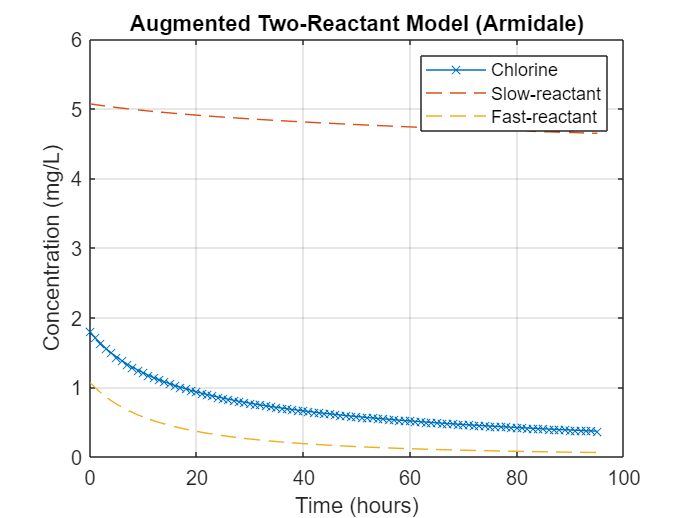

clear ('Cl', 'Cf', 'Cs', 'Ct')
Dt = 1;
kspan = 0:Dt:95; %in hours
Cl = zeros(1,length(kspan));
Cs = zeros(1,length(kspan));
Cf = zeros(1,length(kspan));
Ct = zeros(1,length(kspan));
% Coefficients from Fisher 2016 (Table 1 and Supplementary Material, Armidale case study at 10 degrees): https://www.tandfonline.com/doi/suppl/10.1080/1573062X.2016.1148180/suppl_file/nurw_a_1148180_sm9961.pdf
Cl(1) = 1.8; % concentration of Chlorine
Cf(1) = 1.07;
Cs(1) = 5.07;
kF20 = 0.18; %  coefficient for fast reactant
kS20 = 0.00562; % coefficient for slow reactant
EdivR = 12300;
T=10; % temperature of water sample
ka = 0.04; % value from Fisher (Also check https://awwa.onlinelibrary.wiley.com/doi/full/10.1002/awwa.1183 @ Table 1)

kf = kF20 * exp(-EdivR * (20-T)/(273+20)/(273+T));
ks = kS20 * exp(-EdivR * (20-T)/(273+20)/(273+T));

for k = 1:size(kspan,2)-1
    Cl(k+1) = Cl(k) + Dt*(-ks*Cs(k)*Cl(k)-kf*Cf(k)*Cl(k)); 
    Cs(k+1) = Cs(k) + Dt*(-ks*Cs(k)*Cl(k));
    Cf(k+1) = Cf(k) + Dt*(-kf*Cf(k)*Cl(k));
    Ct(k+1) = Ct(k) + Dt*(ka*(ks*Cs(k)*Cl(k)+kf*Cf(k)*Cl(k)));
end

figure
plot(kspan, Cl, '-x')
grid on
hold all
plot(kspan, Cs,'--')
plot(kspan, Cf,'--')
xlabel('Time (hours)')
ylabel('Concentration (mg/L)')
legend 'Chlorine' 'Slow-reactant' 'Fast-reactant'
title ('Augmented Two-Reactant Model (Armidale)')

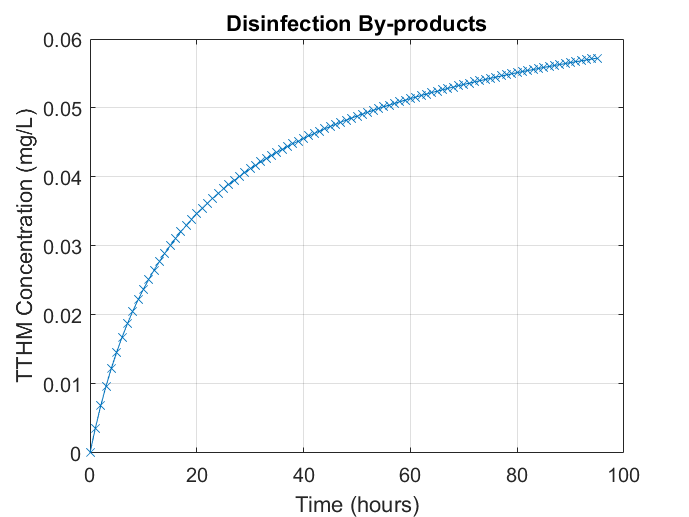


figure
plot(kspan, Ct, '-x')
grid on
xlabel('Time (hours)')
ylabel('TTHM Concentration (mg/L)')
%legend 'Chlorine' 'Slow-reactant' 'Fast-reactant'
title ('Disinfection By-products')

**Modelling of reactions with contaminants**

In a similar way it is possible to simulate the reactions of disinfection substances with contaminants. For instance, the reaction of chlorine with arsenite can be described as:


$$\frac{dC}{dt} = -k_b C(t) - \frac{k_2}{M_{As_3}} C(t) As_3(t)$$



$$\frac{dAs_3}{dt} = \frac{k_2}{M_{C}} C(t) As_3(t) + U_{As_3}(k)$$



$$\frac{dAs_5}{dt} = \frac{k_2 M_{As_5} M_{As_3}}{M_{C}} C(t) As_3(t)$$


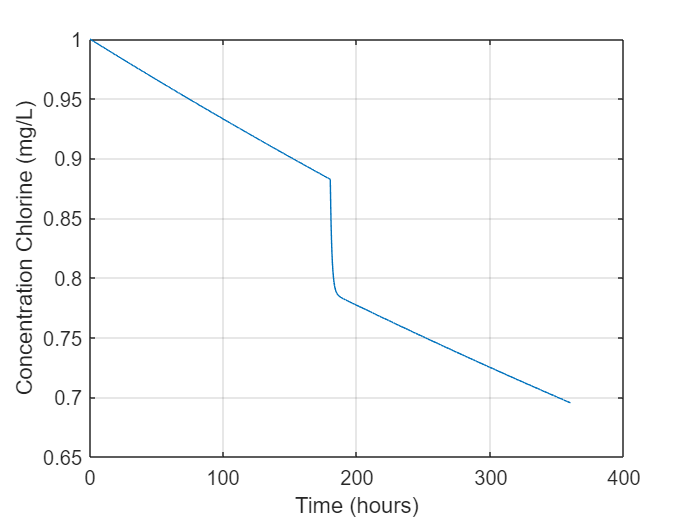

clear ('Cl', 'As3', 'As5')
Dt = 0.01;
Tsim = 6;% hours
kspan = 0:Dt:(60*Tsim); 
Cl = zeros(1,length(kspan));
As3 = zeros(1,length(kspan));
As5 = zeros(1,length(kspan));
UAs3 = zeros(1,length(kspan));
Cl(1) = 1; % concentration of Chlorine
% injection of arsenite at t
UAs3(floor(length(kspan)/2)) = 0.1;
kb = 1/24/60; % bulk chlorine decay rate
k2 = 100000/24/60; % arsenite oxidation velocity
MWCl = 70.9; %mg/mmol
MWAs3 = 74.92; %mg/mmol
MWAs5 = 74.92; %mg/mmol

for k = 1:size(kspan,2)-1
    Cl(k+1) = Cl(k) + Dt*(-kb*Cl(k) - k2/MWAs3 * Cl(k)*As3(k)); 
    As3(k+1) = As3(k) + Dt*(-k2/MWCl * Cl(k)*As3(k)) + UAs3(k);
    As5(k+1) = As5(k) + Dt*(k2*MWAs5*MWAs3/MWCl * Cl(k)*As3(k));
end

figure
plot(kspan, Cl, '-')
grid on
xlabel('Time (hours)')
ylabel('Concentration Chlorine (mg/L)')

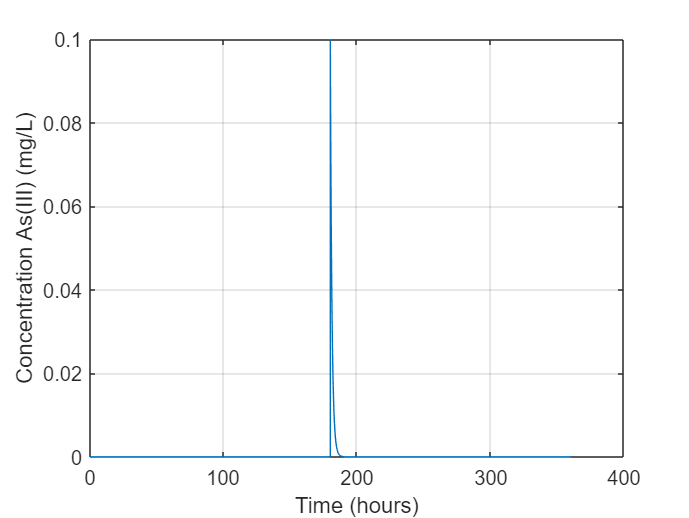


figure
plot(kspan, As3,'-')
xlabel('Time (hours)')
ylabel('Concentration As(III) (mg/L)')
grid on

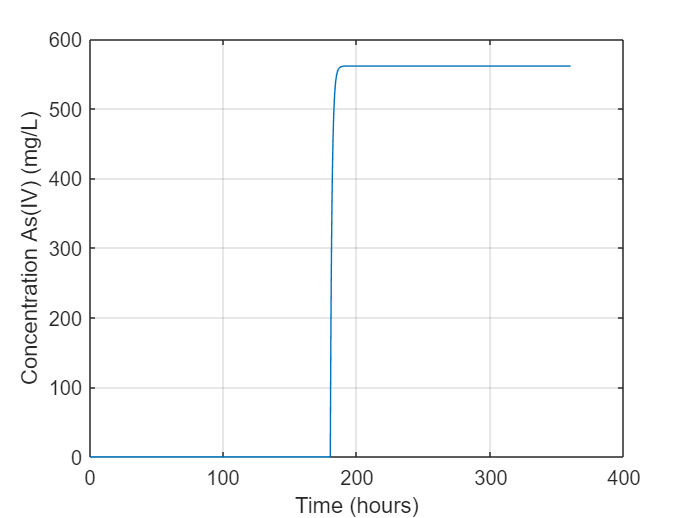


figure
plot(kspan, As5,'-')
grid on
xlabel('Time (hours)')
ylabel('Concentration As(IV) (mg/L)')

**Modelling reactions with pipe wall**

[https://www.tandfonline.com/doi/full/10.1080/1573062X.2020.1804595](https://www.tandfonline.com/doi/full/10.1080/1573062X.2020.1804595)

Simple model from EPANET

EXPBIO model

**Modelling Advection using the Finite Volume Method (Forward Euler)**

To illustrate how to solve numberical the quality dynamics in a pipe, consider the following network

G = epanet('smallnet4.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "smallnet4.inp"...
Input File "smallnet4.inp" loaded sucessfuly.


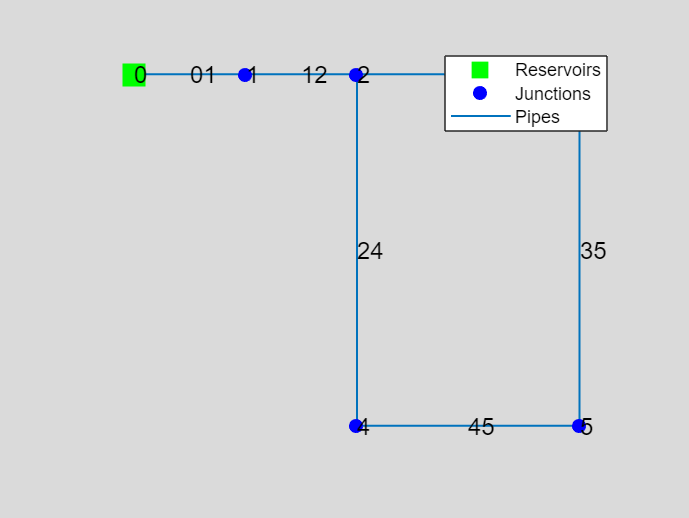

G.plot('nodes', 'yes', 'fontsize', 12, 'links', 'yes', 'fontsize', 12);

The goal is to estimate the chemical concentration at Node 5, by using the Finite Volume Method (FVM). 

First we solve the hydraulics

Lnames = G.getLinkNameID

Lnames = 1×6 cell array
    {'01'}    {'12'}    {'23'}    {'24'}    {'35'}    {'45'}


Nnames = G.getNodeNameID

Nnames = 1×6 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'0'}


L = G.getLinkLength % length in meters

L =          500        3200        1600        1600        1600        1600


D = G.getLinkDiameter % diameter in millimeters

D =    450   450   350   250   300   250


R = G.getLinkRoughnessCoeff % unitless roughness coefficient

R =    100   100   100   100   100   100


H = G.getComputedHydraulicTimeSeries % computes the hydraulics

H = struct with fields:
             Time: [289×1 double]
         Pressure: [289×6 double]
           Demand: [289×6 double]
    DemandDeficit: [289×6 double]
             Head: [289×6 double]
       TankVolume: [289×6 double]
             Flow: [289×6 double]
         Velocity: [289×6 double]
         HeadLoss: [289×6 double]
           Status: [289×6 double]
          Setting: [289×6 double]
           Energy: [289×6 double]
       Efficiency: [289×6 double]


V = max(H.Velocity) % computed velocity in meters/second (maximum value)

V =     0.2096    0.2096    0.0988    0.0893    0.0559    0.0327


F = max(H.Flow); % computed flows in m3/hour

We then find the smallest Dt, which corresponds to he smallest travel time.

T = L./V/60 % minutes (travel time) 

T =    39.7605  254.4674  269.8444  298.7792  476.9341  816.4107


Dt = min(T) % time step in minutes

Dt = 39.7605

Compute the number of finite volumes, as well as the lambda values

FV = floor(T./Dt) % number of finite volumes per pipe

FV =      1     6     6     7    11    20


nFV = sum(FV) % number of finite volumes created

nFV = 51

DL = L./FV % lengths of finite volumes in each pipe

DL =   500.0000  533.3333  266.6667  228.5714  145.4545   80.0000


lambda = Dt * 60 * V./DL % compute the Courant values for each pipe

lambda =     1.0000    0.9375    0.8841    0.9315    0.9170    0.9740


Compute the A matrix using the Forward Euler method

a(1) = 0;
b(1) = 0;

for i = 1:6
    a(i) = sum(FV(1:i))+1;
    b(i) = sum(FV(1:i));
end

A0 = zeros(nFV);

% Connect the "ghost cells"
A0(a(1),b(1)) = lambda(2);
A0(a(2),b(2)) = lambda(3);
A0(a(3),b(2)) = lambda(4);
A0(a(4),b(3)) = lambda(5);
A0(a(5),b(4)) = lambda(6);
 
Adiag = [];
LAdiag = [];
for i = 1:length(FV)
    Adiag = [Adiag, 1 - lambda(i) * ones(1, FV(i))];
    LAdiag = [LAdiag, 0, lambda(i) * ones(1, FV(i)-1)];
end

A2 = diag(LAdiag(2:end));
A2 = [zeros(1,length(A2)); A2];
A2 = [A2, zeros(nFV,1)];

A = A0 + diag(Adiag) + A2

A =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.9375    0.0625         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Setup the simulation parameters

Tsimh = 40;
Tsim = floor(Tsimh*60/Dt);



Solve state-space equation


$$x(k+1) = A x(k) + u(k)$$



$$y(k) = C x(k)$$


y = zeros(1, Tsim)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x = zeros(nFV,Tsim);
u = zeros(nFV,1);
C = zeros(1,nFV)

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


u(1) = 1;

% Compute the weights for the output vector
C(b(5)) = F(5)/(F(5)+F(6));
C(b(6)) = F(6)/(F(5)+F(6));

for k = 1: Tsim
    y(k) = C*x(:,k);
    x(:,k+1) = A * x(:,k) + u;
end


Compute the estimated concentration using EPANET, and compare the results

Q = G.getComputedQualityTimeSeries % computes the quality 

Q = struct with fields:
            Time: [289×1 double]
     NodeQuality: [289×6 double]
     LinkQuality: [289×6 double]
    MassFlowRate: [289×6 double]


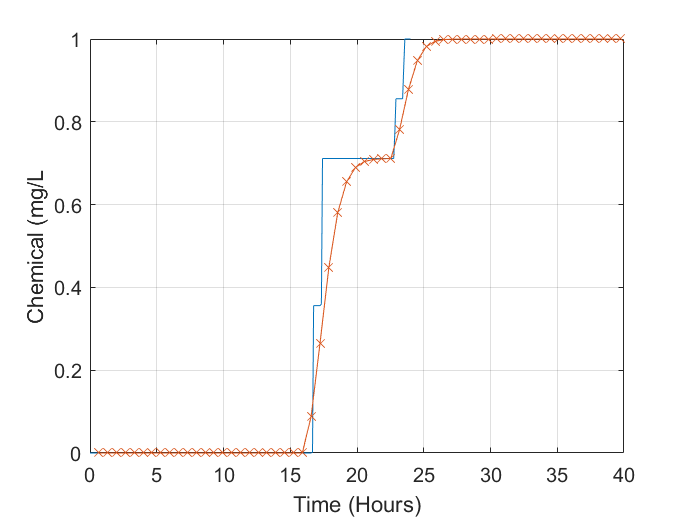


figure
plot(Q.Time/60/60,Q.NodeQuality(:,5))
hold all
plot((1:Tsim)*Dt/60, y, '-x')
grid on
xlabel('Time (Hours)')
ylabel('Chemical (mg/L')


% eigenvalues of velocity must be  positive (check LeVeque 1998)

**Modelling Advection using the Finite Volume Method (Lax Wendrof) **

To illustrate how to solve numberical the quality dynamics in a pipe, consider the following network

G = epanet('smallnet4.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "smallnet4.inp"...
Input File "smallnet4.inp" loaded sucessfuly.


G.plot('nodes', 'yes', 'fontsize', 12, 'links', 'yes', 'fontsize', 12);

The goal is to estimate the chemical concentration at Node 5, by using the Finite Volume Method (FVM). 

First we solve the hydraulics

Tsimh = 30; % hours of simulation
G.setTimeSimulationDuration(Tsimh*60*60);
Lnames = G.getLinkNameID;
Nnames = G.getNodeNameID;
L = G.getLinkLength; % length in meters
D = G.getLinkDiameter; % diameter in millimeters
R = G.getLinkRoughnessCoeff; % unitless roughness coefficient
H = G.getComputedHydraulicTimeSeries; % computes the hydraulics
V = max(H.Velocity) % computed velocity in meters/second (maximum value)

V =     0.2096    0.2096    0.0988    0.0893    0.0559    0.0327


F = max(H.Flow); % computed flows in m3/hour

We then find the smallest Dt, which corresponds to he smallest travel time.

T = L./V/60; % minutes (travel time) 
Dt = min(T); % time step in minutes

Compute the number of finite volumes, as well as the lambda values

FV = floor(T./Dt); % number of finite volumes per pipe
nFV = sum(FV); % number of finite volumes created
DL = L./FV; % lengths of finite volumes in each pipe
lambda = Dt * 60 * V./DL; % compute the Courant values for each pipe


Compute the A matrix using the Lax Wendroff method


$$x_i(k+1) = \frac{\lambda}{2}(1+\lambda) x_{i-1}(k) + (1-\lambda^2)x_i(k) - \frac{\lambda}{2}(1-\lambda) x_{i+1}(k)$$


w0 = lambda'./2.*(1+lambda');
w1 = (1-(lambda.^2)');
w2 = -lambda'./2.*(1-lambda');

a(1) = 0;
b(1) = 0;

for i = 1:6
    a(i) = sum(FV(1:i))+1;
    b(i) = sum(FV(1:i));
end

A0 = zeros(nFV);
A1 = zeros(nFV);
A4 = zeros(nFV);

for i = 1:6
    A0(b(i),b(i)) = w1(i)+w2(i);
end
% Connect the "ghost cells"
A0(a(1),b(1)) = w0(2);
A0(a(2),b(2)) = w0(3);
A0(a(3),b(2)) = w0(4);
A0(a(4),b(3)) = w0(5);
A0(a(5),b(4)) = w0(6);

AM = [];
AL = [];
AU = [];
for i = 2:length(FV)
    AL = [AL, 0, w0(i) * ones(1, FV(i)-1)];
    AM = [AM, 0, w1(i) * ones(1, FV(i)-1)];
    AU = [AU, 0, w2(i) * ones(1, FV(i)-1)];
end
AM = [AM 0];
A0 = A0 + diag(AM);
AL = [AL 0];
AL = [zeros(1,51); diag(AL)];
AL(52,:) = [];
A0 = A0 + AL;
AU = [AU 0];
AU = [zeros(51,1), diag(AU)];
AU(:,52) = [];
A = A0 + AU;


Setup the simulation parameters


Tsim = floor(Tsimh*60/Dt);


Solve state-space equation


$$x(k+1) = A x(k) + u(k)$$



$$y(k) = C x(k)$$


y = zeros(1, Tsim)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x = zeros(nFV,Tsim);
z = zeros(nFV,Tsim);
u = zeros(nFV,1);
C = zeros(1,nFV)

C =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


u(1) = 1;
B = eye(nFV);

% Compute the weights for the output vector
C(b(5)) = F(5)/(F(5)+F(6));
C(b(6)) = F(6)/(F(5)+F(6));

for k = 1: Tsim
    y(k) = C*x(:,k);
    x(:,k+1) = A * x(:,k) + w0(1)*u;
end


Compute the estimated concentration using EPANET, and compare the results

Q = G.getComputedQualityTimeSeries % computes the quality 

Q = struct with fields:
            Time: [361×1 double]
     NodeQuality: [361×6 double]
     LinkQuality: [361×6 double]
    MassFlowRate: [361×6 double]


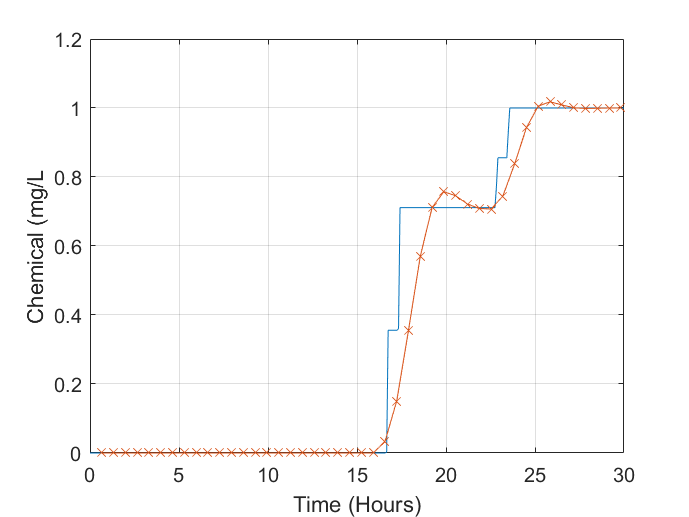


figure
plot(Q.Time/60/60,Q.NodeQuality(:,5))
hold all
plot((1:Tsim)*Dt/60, y, '-x')
grid on
xlabel('Time (Hours)')
ylabel('Chemical (mg/L')

**Advection & Reaction Dynamics**

% solve the equations with a linear decay

**Demonstrate solution of EPANET-MSX?**